c = 3e8

c = 300000000

tau_ski = 20e-9

tau_ski = 2.0000e-08

tau_lfm = 5e-6

tau_lfm = 5.0000e-06

df_lfm = 50e6

df_lfm = 50000000

f_samp = 400e6

f_samp = 400000000

ang_samp = 0.0036

ang_samp = 0.0036

dR_ski = c*tau_ski / 2

dR_ski = 3

Dmin_ski = c*tau_ski / 2

Dmin_ski = 3

data = load('/home/rh1721/Рабочий стол/git/hw-rliik/files/ski03.mat')

data = struct with fields:
       skiraw: [16000×1383 int16]
    skiangles: [1×1383 uint16]


dR_samp = c/2/f_samp

dR_samp = 0.3750

N = size(data.skiraw, 1)

N = 16000

Dmax = N*dR_samp

Dmax = 6000

T_prf = N/f_samp

T_prf = 4.0000e-05

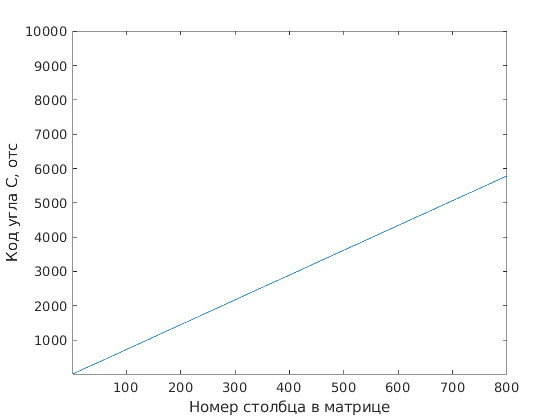

plot(data.skiangles)
xlabel('Номер столбца в матрице')
ylabel('Код угла С, отс')

xlim([2 800])
ylim([10 10010])

Amin_ski = single(min(data.skiangles(:)))*ang_samp

Amin_ski = single
0.0180

Amax_ski = single(max(data.skiangles(:)))*ang_samp

Amax_ski = single
35.9892

cutrange = medfilt1(20*log10(abs(single(data.skiraw(:, 1)))), 50)

'medfilt1' requires Signal Processing Toolbox.

plot(cutrange)
xlabel('Каналы дальности, отс')
ylabel('Амплитуда, отс')
